clear all;
clc;
RR=10000; %amount of trials ran
for Q=1:RR;
       if (Q<RR)
sym n;
sym k;
sym z;
n=300; % used to make data
z=900; % sample size

fc = 20; %in Hz
fs = 250;%in Hz

F= zeros(n,1);
error=zeros(n,1);
count=zeros(n,1);
sym x;
x=0;
k=0;
count =1;

%creation of dummy data
for i=1:z;
            
    if(i>(8*n/3))
        k=1;
    else if(i>(7*n/3))
        k = 3;
    else if(i>(2*n))
        k = -5*(x/(4*n/3))+15;
    else if(i > (5*n/3))
        k = (x/(n/3));
    else if (i > 4*n/3)
        k = 2;
    else if(i>n)
        k = 3;
    else if(i>(2*n/3))
        k = -5*(x/(2*n/3))+15;
    else if(i > (n/3))
        k = 5*(x/(n/3));
    else if (i > 0)
        k = 2;
    end
    end
    end
    end
    end
    end
    end
    end
    end


      x=i;
      y(i, :)=abs(25*k+5);
      F=awgn(y,11,"measured");%adds noise to the data
      count(i, :)=i;    
      i=i+1;
end




3rd order filters

%All 3rd order Filter Responses%
%Butterworth
%"butterworth"
[but3_a,but3_b]=butter(3,fc/(fs/2)); %3rd order Butterworth
filtButter_3=filter(but3_a,but3_b,F);


for i=100:z-100;
    
experience_value = filtButter_3(i);
theoritical_value =y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;

    i=i+1;
end
ErrorButter_3(Q, :)=mean(abs(percentage_error));



%"Elliptic"
%Elliptic Filter
[elip3_a,elip3_b]=ellip(3,2,40,fc/(fs/2));
filtEllip_3=filter(elip3_a,elip3_b,F);

for i=100:z-100;
    
experience_value = filtEllip_3(i);
theoritical_value =y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;

    i=i+1;
end
ErrorElip_3(Q, :)=mean(abs(percentage_error));


%Bessel FIlter
%"Bessel"
[bes3_a,bes3_b]=besself(5, [fc/(fs/2)],'low');
filtBess_3=filter(bes3_a,bes3_b,F);

for i=100:z-100;
    
experience_value = filtBess_3(i);
theoritical_value =y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;

    i=i+1;
end
ErrorBess_3(Q, :)=mean(abs(percentage_error));

%Cheby 1 Filter
%"Cheby"
[cheb3_a,cheb3_b] = cheby1(3,3,fc/(fs/2));
filtCheb_3=filter(cheb3_a,cheb3_b,F);

for i=100:z-100;
    
experience_value = filtCheb_3(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;

    i=i+1;
end
ErrorCheb1_3(Q, :)=mean(abs(percentage_error));


%Cheby 2 (Inverse) Filter
%"Cheby 2"
[cheb2_3_a,cheb2_3_b] = cheby2(3,3,fc/(fs/2));
filtCheb2_3=filter(cheb2_3_a,cheb2_3_b,F);

for i=100:z-100;
    
experience_value = filtCheb2_3(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;

    i=i+1;
end
ErrorCheb2_3(Q, :)=mean(abs(percentage_error));

5th orders


%Butter_5th Error
[but5_a,but5_b]=butter(5,fc/(fs/2)); %5rd order Butterworth
filtButter_5=filter(but5_a,but5_b,F);
for i=100:z-100;
    
experience_value = filtButter_5(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;    
    i=i+1;
end
ErrorButter_5(Q, :)=mean(abs(percentage_error));

%Cheb_5 Error
[cheb5_a,cheb5_b] = cheby1(5,3,fc/(fs/2));
filtCheb_5=filter(cheb5_a,cheb5_b,F);

for i=100:z-100;
experience_value = filtCheb_5(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;    
    i=i+1;
end
ErrorCheb_5(Q, :)=mean(abs(percentage_error));

%Cheb2_5 Error
[cheb2_5_a,cheb2_5_b] = cheby2(5,3,fc/(fs/2));
filtCheb2_5=filter(cheb2_5_a,cheb2_5_b,F);

for i=100:z-100;
experience_value = filtCheb2_5(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;    
    i=i+1;
end
ErrorCheb2_5(Q, :)=mean(abs(percentage_error));

%Bessel_5 Error
[bes5_a,bes5_b]=besself(5, fc/(fs/2));
filtBess_5=filter(bes5_a,bes5_b,F);

for i=100:z-100; 
experience_value = filtBess_5(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;    
    i=i+1;
end
ErrorBess_5(Q, :)=mean(abs(percentage_error));

%Ellip_5 Error
[elip5_a,elip5_b]=ellip(5,2,40,fc/(fs/2));
filtEllip_5=filter(elip5_a,elip5_b,F);

for i=100:z-100;
experience_value = filtEllip_5(i);
theoritical_value = y(i);
percentage_error(i, :) =((experience_value-theoritical_value)/theoritical_value)*100;    
    i=i+1;
end
ErrorEllip_5(Q, :)=mean(abs(percentage_error));

%loop ends
end
end


Errors

%Errors os 3rd order
ErrorButter_3_Avg=mean(ErrorButter_3)

ErrorButter_3_Avg = 11.8188


ErrorElip_3_Avg=mean(ErrorElip_3)

ErrorElip_3_Avg = 11.5020


ErrorBess_3_Avg=mean(ErrorBess_3)

ErrorBess_3_Avg = 87.6199


ErrorCheb1_3_Avg=mean(ErrorCheb1_3)

ErrorCheb1_3_Avg = 11.5866


ErrorCheb2_Avg=mean(ErrorCheb2_3)

ErrorCheb2_Avg = 14.9357

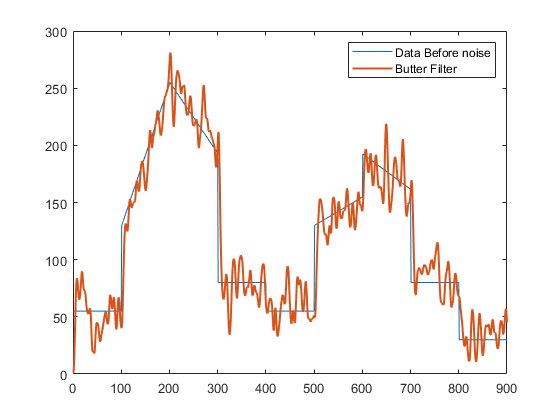




%plots
plot(y)
hold on
plot(filtButter_3,"LineWidth",1.5)
hold off
legend("Data Before noise","Butter Filter")

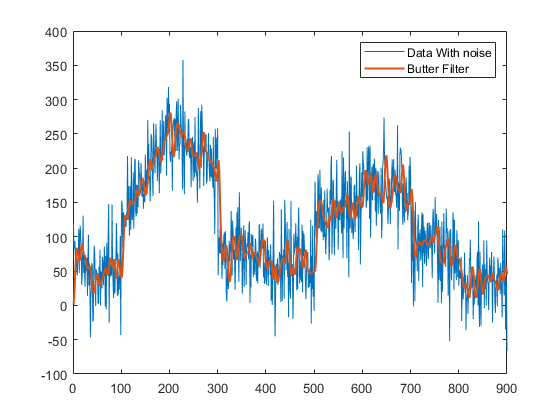


plot(F)
hold on
plot(filtButter_3,"LineWidth",1.5)
hold off
legend("Data With noise","Butter Filter")

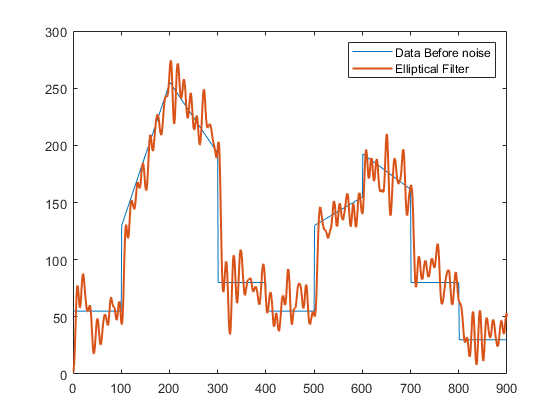






plot(y)
hold on
plot(filtEllip_3,"LineWidth",1.5)
hold off
legend("Data Before noise","Elliptical Filter")

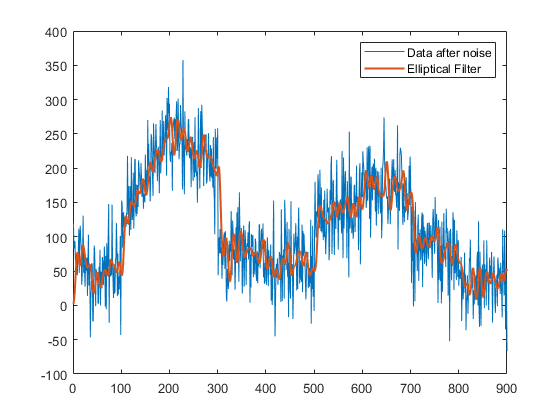


plot(F)
hold on
plot(filtEllip_3,"LineWidth",1.5)
hold off
legend("Data after noise","Elliptical Filter")

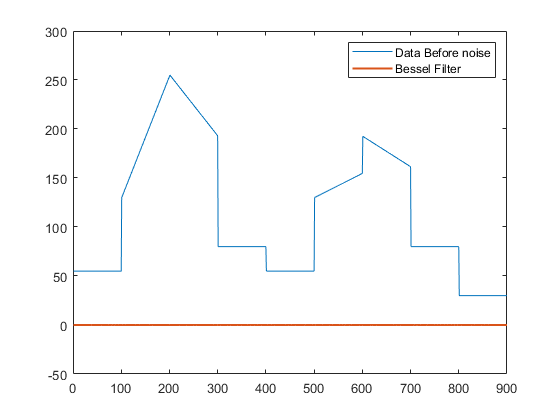




plot(y)
hold on
plot(filtBess_3,"LineWidth",1.5)
hold off
legend("Data Before noise","Bessel Filter")

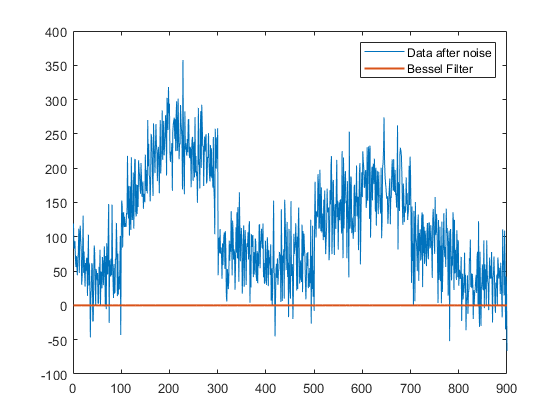


plot(F)
hold on
plot(filtBess_3,"LineWidth",1.5)
hold off
legend("Data after noise","Bessel Filter")

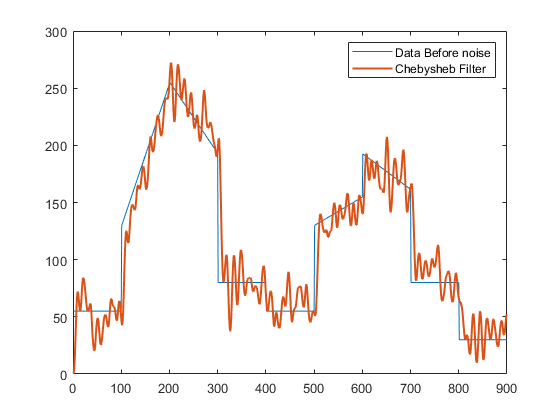


plot(y)
hold on
plot(filtCheb_3,"LineWidth",1.5)
hold off
legend("Data Before noise","Chebysheb Filter")

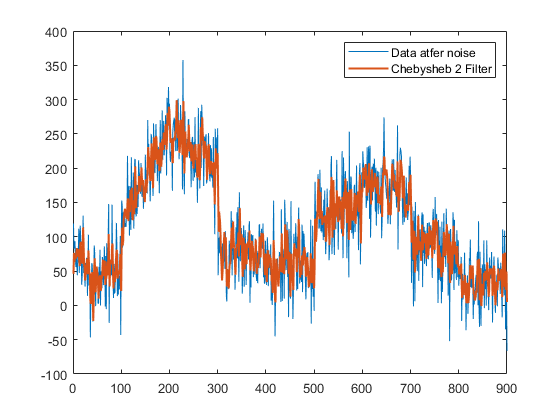


plot(F)
hold on
plot(filtCheb2_3,"LineWidth",1.5)
hold off
legend("Data atfer noise","Chebysheb 2 Filter")

%Error of 5th order
ErrorButter_5_Avg=mean(ErrorButter_5)

ErrorButter_5_Avg = 12.9363


ErrorEllip_5_Avg=mean(ErrorEllip_5)

ErrorEllip_5_Avg = 12.2445


ErrorBess_5_Avg=mean(ErrorBess_5)

ErrorBess_5_Avg = 87.6199


ErrorCheb_5_Avg=mean(ErrorCheb_5)

ErrorCheb_5_Avg = 13.9481


ErrorCheb2_5_Avg=mean(ErrorCheb2_5)

ErrorCheb2_5_Avg = 15.7455

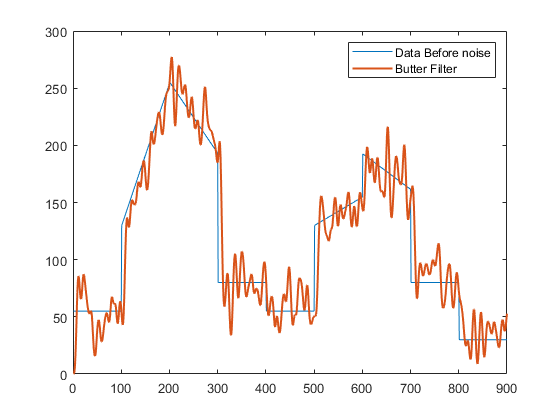

%plots
plot(y)
hold on
plot(filtButter_5,"LineWidth",1.5)
hold off
legend("Data Before noise","Butter Filter")

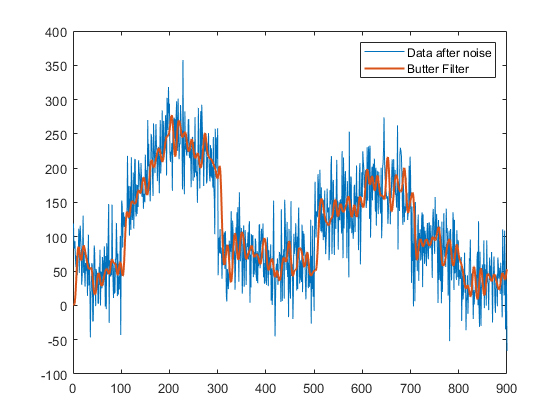


plot(F)
hold on
plot(filtButter_5,"LineWidth",1.5)
hold off
legend("Data after noise","Butter Filter")

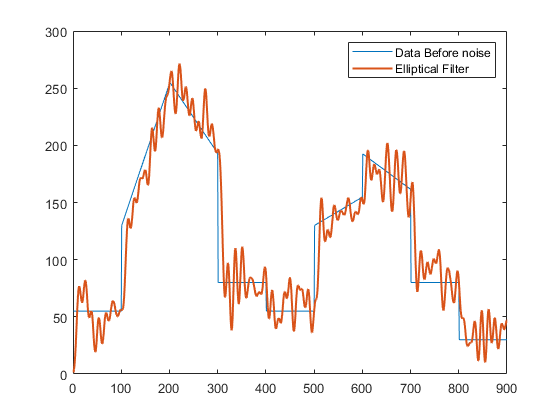



plot(y)
hold on
plot(filtEllip_5,"LineWidth",1.5)
hold off
legend("Data Before noise","Elliptical Filter")


plot(F)
hold on
plot(filtBess_5,"LineWidth",1.5)
hold off
legend("Data after noise","Bessel Filter")

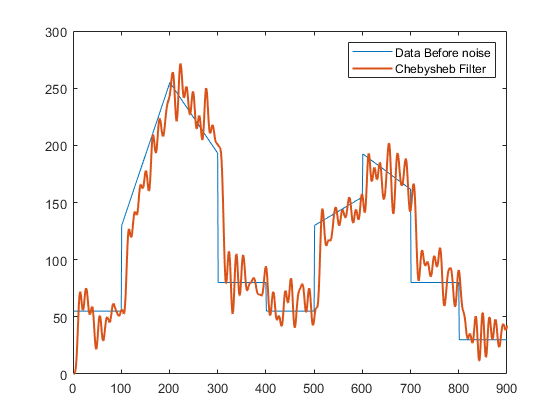


plot(y)
hold on
plot(filtCheb_5,"LineWidth",1.5)
hold off
legend("Data Before noise","Chebysheb Filter")

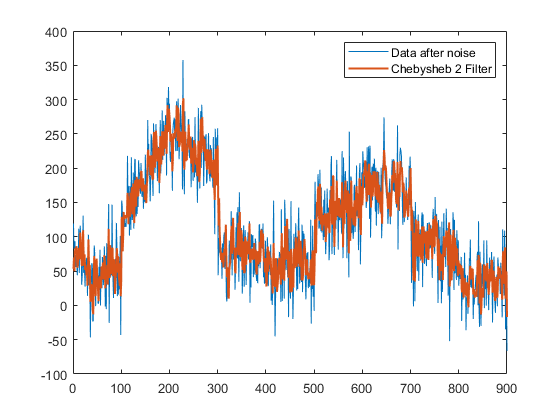


plot(F)
hold on
plot(filtCheb2_5,"LineWidth",1.5)
hold off
legend("Data after noise","Chebysheb 2 Filter")